# Group Assignment 03 

# Playing dices

### I et terningespil kastes en terning tre gange og det samlede antal øjne i de tre slag tælles. Den stokastiske variabel X angiver summen af de tre slag. Terningen kan antages for ideel.

1)** Hvor mange muligheder er der for, at X er hhv. 3, 4,…, 18?**

Mulighederne for alle udfald findes ved at gange alle udfald i hvert terningekast. Da de er uafhængige kan dette lade sige gøre. 

pr_abc = 6*6*6

pr_abc = 216

2) **Opskriv og tegn pmf’en fX(x) for X**

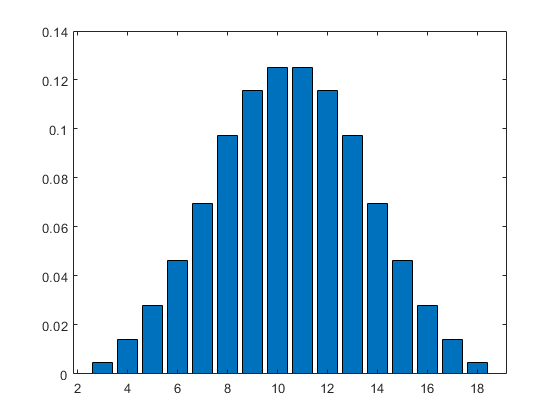

posibilities = [3:18];
Outcomes = [1 3 6 10 15 21 25 27 27 25 21 15 10 6 3 1];
% Display fraction
format rational
probability_outcomes = Outcomes * 1/pr_abc;
bar(posibilities, probability_outcomes)

3) **Opskriv og tegn cdf’en FX(x) for X.**

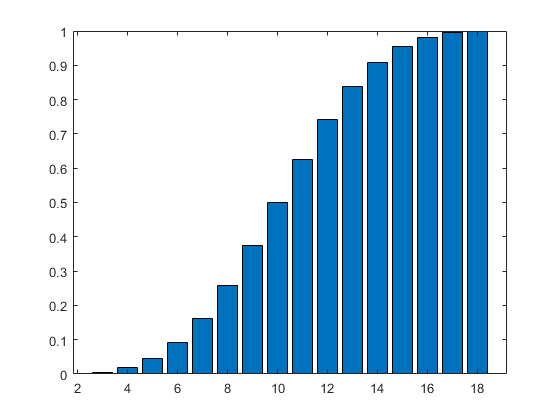

prob_sum = cumsum(probability_outcomes);
bar(posibilities, prob_sum)

4) Hvad er sandsynligheden for at få 8?

eight_index = find(posibilities == 8);
format 
prob_eight = probability_outcomes(eight_index)

prob_eight = 0.0972

5) Hvad er sandsynligheden for at få mindst 12?

twelwe_i = find(posibilities == 12);
format 
prob_twelve = prob_sum(twelwe_i)

prob_twelve = 0.7407

6) Hvad er sandsynligheden for at få mindst 9 og højst 15?

nine_i = find(posibilities == 9);
fifteen_i = find(posibilities == 15);
prob_9_15 = prob_sum(fifteen_i) - prob_sum(nine_i)

prob_9_15 = 0.5787

7) Hvad er sandsynligheden for at få færre end 4 eller flere end 16? ( Pr(X < 4 or X > 16) )

four_i = find(posibilities == 4);
sixt_i = find(posibilities == 16);
less_4_more_16 = prob_sum(four_i -1) + prob_sum(16) - prob_sum(sixt_i)

less_4_more_16 = 0.0231

8) Hvad er det gennemsnitlige antal, man kan forvente at slå?

Matlab and formula

lab_mean = mean(posibilities)

lab_mean = 10.5000

form_mean = sum(posibilities)/length(posibilities)

form_mean = 10.5000

9) Hvad er variansen og standard afvigelsen af antallet? 

Formula

x_2 = posibilities.^2;
EX2 = sum(x_2.*probability_outcomes)

EX2 = 119.0000

form_var = (EX2) - form_mean^2

form_var = 8.7500

10) 

Something does not add up??

std_dev = sqrt(form_var);
mean_plus = lab_mean + std_dev;
mean_min = lab_mean - std_dev;

lower_bound = int8(mean_min)-1;
upper_bound = cast(mean_plus, 'int8');
low_bound_i = find(posibilities == lower_bound);
upper_bound_i = find(posibilities == upper_bound);
first_std_var_sum = prob_sum(upper_bound_i) - prob_sum(low_bound_i)

first_std_var_sum = 0.6759

std_dev = sqrt(form_var) * 2;
mean_plus = lab_mean + std_dev;
mean_min = lab_mean - std_dev;

lower_bound = int8(mean_min)-1;
upper_bound = cast(mean_plus, 'int8');
low_bound_i = find(posibilities == lower_bound);
upper_bound_i = find(posibilities == upper_bound);
scnd_std_var_sum = prob_sum(upper_bound_i) - prob_sum(low_bound_i)

scnd_std_var_sum = 0.9630

std_dev = sqrt(form_var) * 3

std_dev = 8.8741

mean_plus = lab_mean + std_dev

mean_plus = 19.3741

mean_min = lab_mean - std_dev

mean_min = 1.6259


lower_bound = int8(mean_min)-1;
upper_bound = cast(mean_plus, 'int8');
low_bound_i = find(posibilities == lower_bound);
upper_bound_i = find(posibilities == upper_bound);
third_std_var_sum = prob_sum(upper_bound_i) - prob_sum(low_bound_i)


third_std_var_sum =

  1×0 empty double row vector



Since the third and the bounds are too high and out of scope, it just means that it includes everything, meaning that there is a Pr(mu - 3 * std <= X <= mu + 3 * std) = 1 or = 100%

11) Hvis den første terning er en 6’er, hvad er så sandsynligheden for at den samlede sum for de tre slag er mindst 12?

pr_six = 1/6

pr_six = 0.1667

tot_prob = (1/6) * ((1+2+3+4+5+6)/6) % This should be the right answer

tot_prob = 0.5833